# II. Quantum EigenModes of a Potential

Schrodinger equation: 


$$i\hbar\frac{\partial\Psi}{\partial t} = -\frac{\hbar^2}{2m}\frac{\partial^2\Psi}{\partial z^2} + V(z)\Psi$$


When we consider the time dependent wavefunction to be representable as $\Psi(z,t) = \psi(z)e^{-iEt/\hbar}$ then we can write the time independent schrodinger equation as 


$$E_j \psi_j(z) = -\frac{\hbar^2}{2m}\frac{d^2\psi_j}{dz^2} + V(z)\psi_j\quad,\quad j = 0,1,2,3,\dots$$


We'll represent the solutions to this equation for the quantum harmonic oscillator as the hermite guassian solution set. 

$\psi_j(z) = \mathcal{N}_j H_j(z\,/\,z_0)e^{-z^2/2z_0^2}$ where the oscillator length is $z_0 = \sqrt{\frac{\hbar}{m\omega}}$ and $z_j = z_{0}\sqrt{2j + 1}$ 

In order to approach the problem numerically, we need continuous space into a set of discrete points given by $z_\mu = \frac{z_{max}}{2} + (\mu -1)\Delta z\quad,\quad \mu = 1,2,\dots,N$ where $\Delta z = z_{max}/(N-1)$

The second approximation is performed on the second derivative $\frac{d^2\psi}{dz^2}\rightarrow \frac{(\psi_{\mu+1} - 2\psi_\mu +\psi_{\mu-1})}{\Delta z^2}$ such that we can write the hamiltonian as 


$$H_{\mu,\nu} = \bigl[V_\mu + \frac{\hbar^2}{m\Delta z^2}\bigl]\delta_{\mu,\nu} - \frac{\hbar^2}{2m\Delta z^2}[\delta_{\mu,\nu +1} + \delta_{\mu,\nu - 1}]$$


$\Delta z << z_0$ and $z_{max} >> z_0$

b.) We know that the normalization condition for the wavefunction in coordinate space is 


$$1 = \int_{-\infty}^{\infty} |\Psi(z)|^{2}dz$$


We also know that produces normalized eigenvectors that satisfy a normalization condition: 


$$1 = \sum\limits_{\mu}|\upsilon_{\mu}|^{2}$$


We can then infer that the eigenvectors produced by matlab from the discrete matrix representation of the hamiltonian does not directly produce something that is a wavefunction.

To remedy this issue, we look at discretizing the normalization condition for the coordinate space wavefunction. 


$$\int_{-\infty}^{\infty} |\Psi(z)|^{2}dz \rightarrow \sum\limits_{\mu}\Delta z |\Psi_{\mu}|^{2}= 1$$


We now have a relationship between the wavefunction and the eigenvectors in matlab. 


$$\sum\limits_{\mu}\underbrace{\Delta z|\Psi_{\mu}|^{2}}_{|\upsilon_{\mu}|^{2}}= 1$$


Therefore we can find the wavefunctions by making use of the following relationship: 


$$\Psi_{\mu} = \frac{\upsilon_{\mu}}{\sqrt{\Delta z}}$$


## C. Quantum harmonic oscillator

b.)  

clear; close all;
z0 = 1e-6;   % beam width of 1um

I will choose $\Delta z = z_0/10$ and $z_{max} = 10z_0$

deltaZ = z0/10;     % step size
zmax = 10*z0;        % maximum grid extent
N = zmax/deltaZ + 1;        % number of points in grid

This means that there will be 101 eigenvalue/eigenvector pairs for `eigs` to compute.

mu = 1:N;
z_mu = -zmax/2 + (mu -1)*deltaZ;
h = zeros(N,N);
% create the hamiltonian matrix h
for i = 1:N
    for j = 1:N
        if i == j
            h(i,j) = (1/2)*(z_mu(i)/z0).^2 + (z0/deltaZ)^2;
        elseif i ==(j+ 1) || i == (j - 1)
            h(i,j) = -(1/2)*(z0/deltaZ)^2;
        end
    end
end

I will label the eigenvectors as `V = PSI` and the eigenvalues as `D = E`

% find eigenvectors and eigenvalues
[PSI,E] = eigs(h,N,'smallestabs');

Potential pitfalls of this chosen grid: 

- The criterion that $z_{max} = 10z_0$ make be too finely meshed.

c.) In general, an order of magnitude difference between $\Delta z$ and $z_0$ is good.

deltaZ/z0

ans = 0.1000

We know analytically that $E_j = \hbar\omega(j + 1/2)$ are the eigenvalues of the quantum harmonic oscillator. If we run a check to see the error between the 10 lowest eigenvalues calculated numerically versus the analytic values we get the following:

Ej = eigs(h,10,'smallestabs');
E_analytic = zeros(10,1);
for i=1:10
    E_analytic(i) = (i-1) + 1/2;
end
Tol = E_analytic - Ej % shows a small error between the numeric and the analytic values.

Tol =     0.0003
    0.0016
    0.0041
    0.0078
    0.0128
    0.0191
    0.0264
    0.0340
    0.0395
    0.0363


d.) plotting numeric eigenfunctions and comparing to the analytic solutions

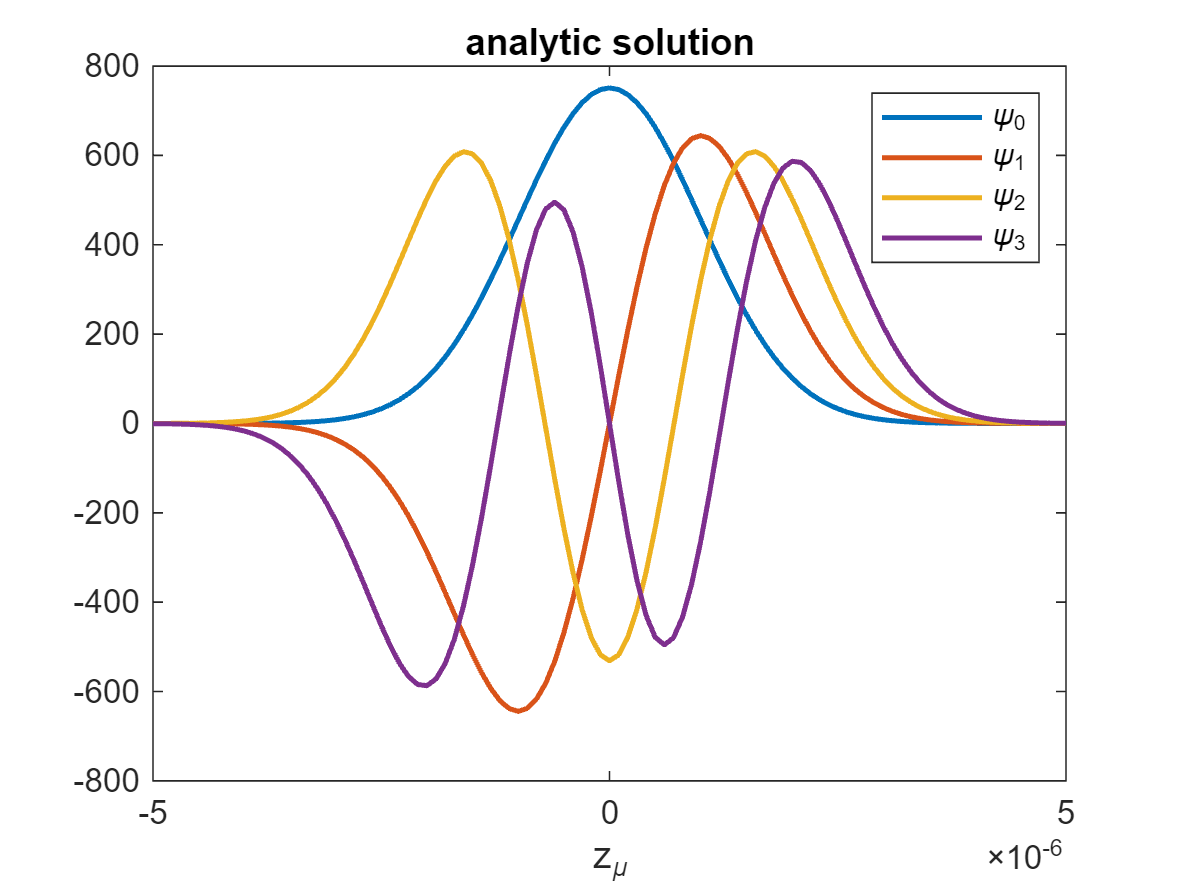

[PSI,~] = eigs(h,4,'smallestabs');
PSI0 = -PSI(:,1)./sqrt(deltaZ);
PSI1 = -PSI(:,2)./sqrt(deltaZ);
PSI2 = -PSI(:,3)./sqrt(deltaZ);
PSI3 = PSI(:,4)./sqrt(deltaZ);
% analytic solutions 
psi0 = (1/pi/z0^2)^(1/4)*exp(-z_mu.^2./(2*z0^2));
psi1 = (1/sqrt(2))*psi0.*hermiteH(1,z_mu/z0);
psi2 = (1/sqrt(8))*psi0.*hermiteH(2,z_mu/z0);
psi3 = (1/sqrt(48))*psi0.*hermiteH(3,z_mu/z0);

% plot analytic
figure(1);
plot(z_mu,psi0,'LineWidth',1.5);
hold on;
plot(z_mu,psi1,'LineWidth',1.5);
plot(z_mu,psi2,'LineWidth',1.5);
plot(z_mu,psi3,'LineWidth',1.5);
hold off;
xlabel('z_\mu');
title('analytic solution');
legend('\psi_0','\psi_1','\psi_2','\psi_3');

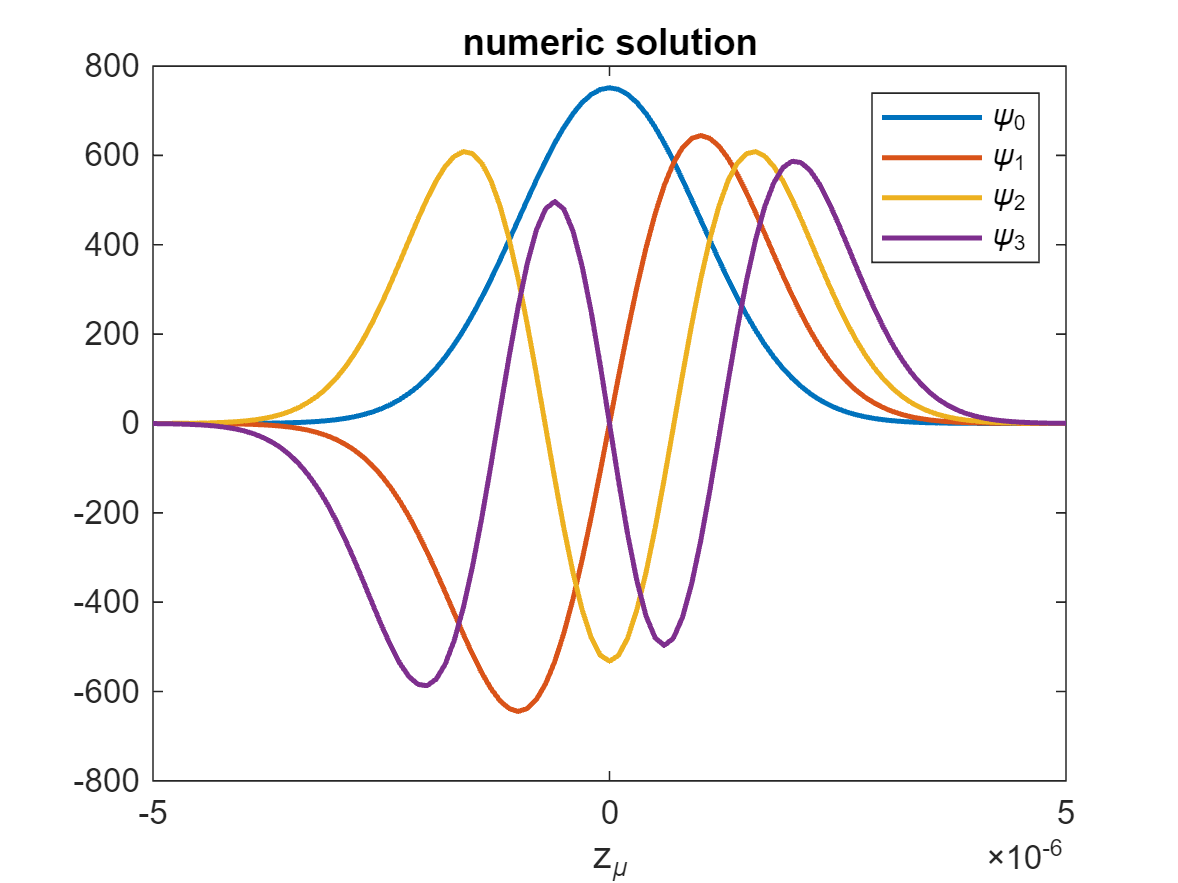


% plot numeric
figure(2);
plot(z_mu,PSI0,'LineWidth',1.5);
hold on;
plot(z_mu,PSI1,'LineWidth',1.5);
plot(z_mu,PSI2,'LineWidth',1.5);
plot(z_mu,PSI3,'LineWidth',1.5);
hold off;
xlabel('z_\mu');
title('numeric solution');
legend('\psi_0','\psi_1','\psi_2','\psi_3');

One crucial result coming from plotting the numeric solutions is that the fact that eigenvectors can be defined somewhat arbitrarily means that there might be extra negative signs attached to all of the components. this was the case for the first 3 eigenfunctions so they have been adjusted accordingly.

e.) $z_j = z_0\sqrt{2j + 1}$

The lattice approximation breaks down when $z_j \geq z_{max}/2$ or $j > j_{max} = (z_{max}/2\sqrt{2}z_0)^2
$

plot ratio $r_{j}= \frac{\epsilon_{j} - (j + 1/2)}{j + 1/2}\quad,\quad j=0,1,\dots,N$

jmax = (zmax/2/sqrt(2)/z0)^2

jmax = 12.5000

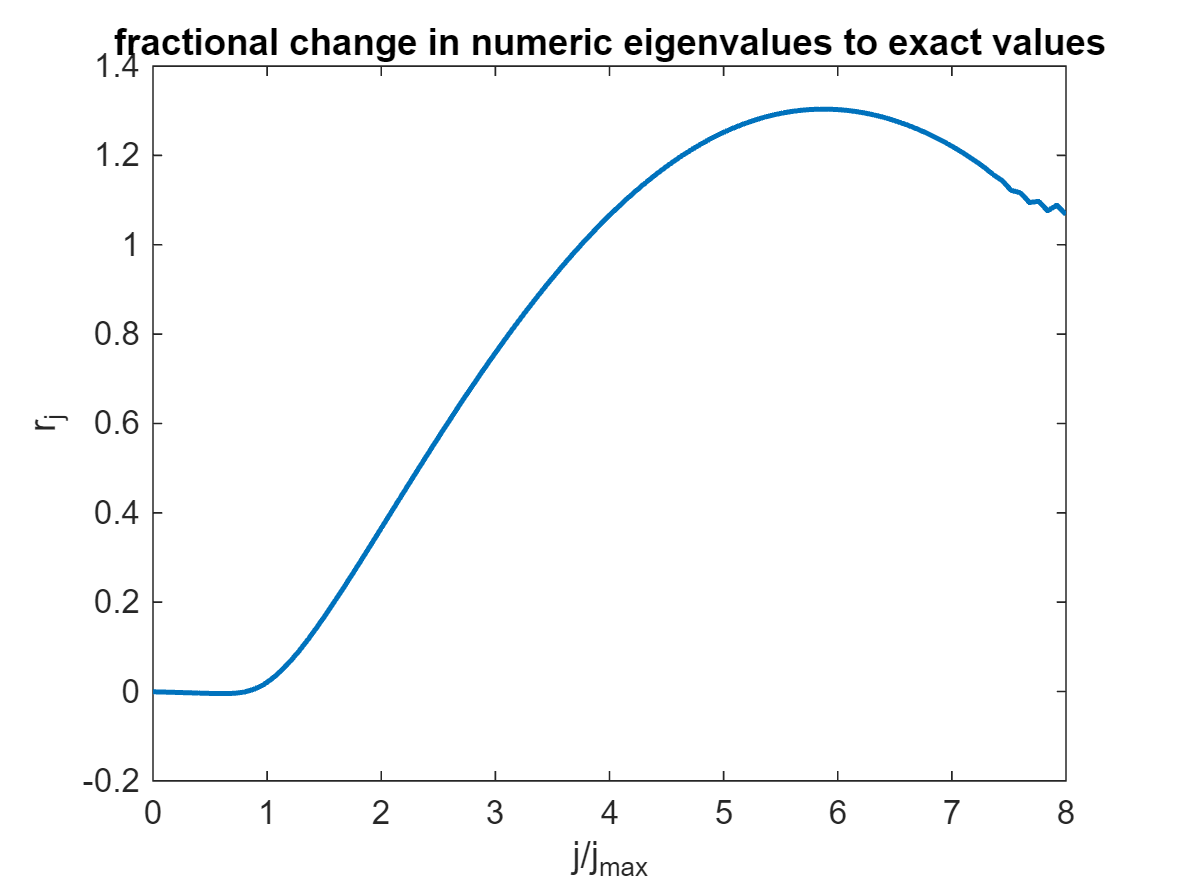

j = mu'-1;
ej = eigs(h,N,'smallestabs'); % get the eigenvalues of h in vector form.
rj = (ej - (j + 1/2))./(j + 1/2);
figure(3);
set(gca,'FontSize',15);
plot(j./jmax,rj,'LineWidth',1.5);
ylabel('r_j');
xlabel('j/j_{max}');
title('fractional change in numeric eigenvalues to exact values');
xlim([0 max(j./jmax)]);
xticks(0:max(j./jmax)); % appropriate values are within j/jmax <= 1